% Lab 4: The Poisson Distribution and RNA-Seq
% BIM 105, Fall 2024
% University of California, Davis

## Q1:

r = poissrnd(10, 1000, 1); 
mr = mean(r);
vr = var(r);
display(mr)

mr = 10.0980

display(vr)

vr = 10.7131

## Q2:

n = 10000; 
p = 0.001; 
lambda = n*p; 
points = 0:1:20; 

pdf_bino = binopdf(points, n, p);
pdf_poiss = poisspdf(points, lambda);

figure('Name', 'Question 2');
bar(points, [pdf_bino', pdf_poiss']);
ylabel("Probability")
xlabel("Outcome")
legend("Binomial", "Poisson")

## Q3:


ti = [200 300 1000 500 450]; % 5 genes, each with a particular length
ni = [5 3 5 7 10]; % Copy numbers of each transcript
np = 200; 

counts = rna_seq_sim(ti, ni, np);


## Q4:

pgenes = (counts./(ti-5))/sum(counts./(ti-5));
display(pgenes)

pgenes =     0.1483    0.0368    0.2070    0.2993    0.3086


## Q5:

display(pgenes)

pgenes =     0.1483    0.0368    0.2070    0.2993    0.3086


ni = [5, 3, 5, 7, 10]

ni =      5     3     5     7    10


display(ni/sum(ni))

    0.1667    0.1000    0.1667    0.2333    0.3333



## Q6:

nSim = 1000; 
count_A = NaN(nSim, 1);

for i = 1:nSim
    counts = rna_seq_sim(ti, ni, np);
    count_A(i) = counts(1); %tallies number of counts for the first gene
end 

figure("Name","Question 6");
histogram(count_A, 'Normalization', 'pdf')
xlabel("Counts")

## Q7:

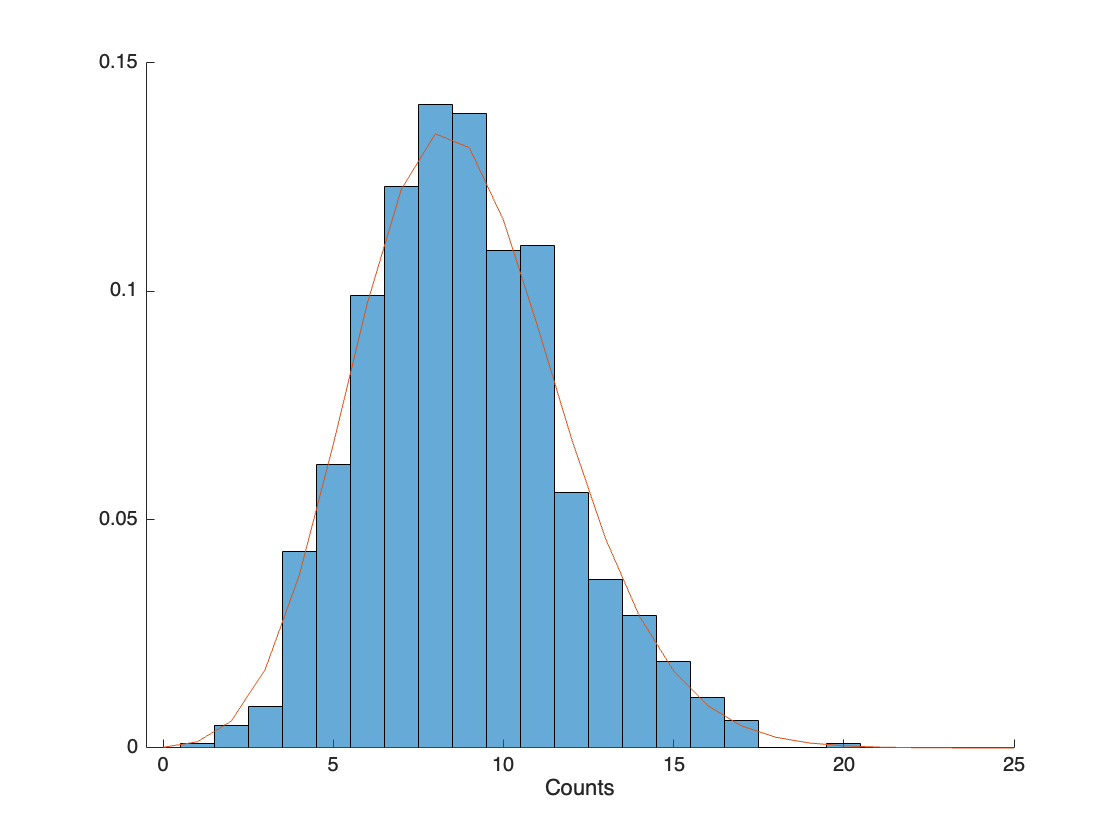

figure("Name","Question 7")
hold on
histogram(count_A, "Normalization", "pdf")
xlabel("Counts")
mc = mean(count_A); % parameter for the Poisson distribution
points = 0:1:25; % generate x-values where the Poisson PDF will be evaluated
% Plot the Poisson probability density function using the mean of count_A as the rate parameter
plot(points, poisspdf(points, mc));
hold off

## Q8:

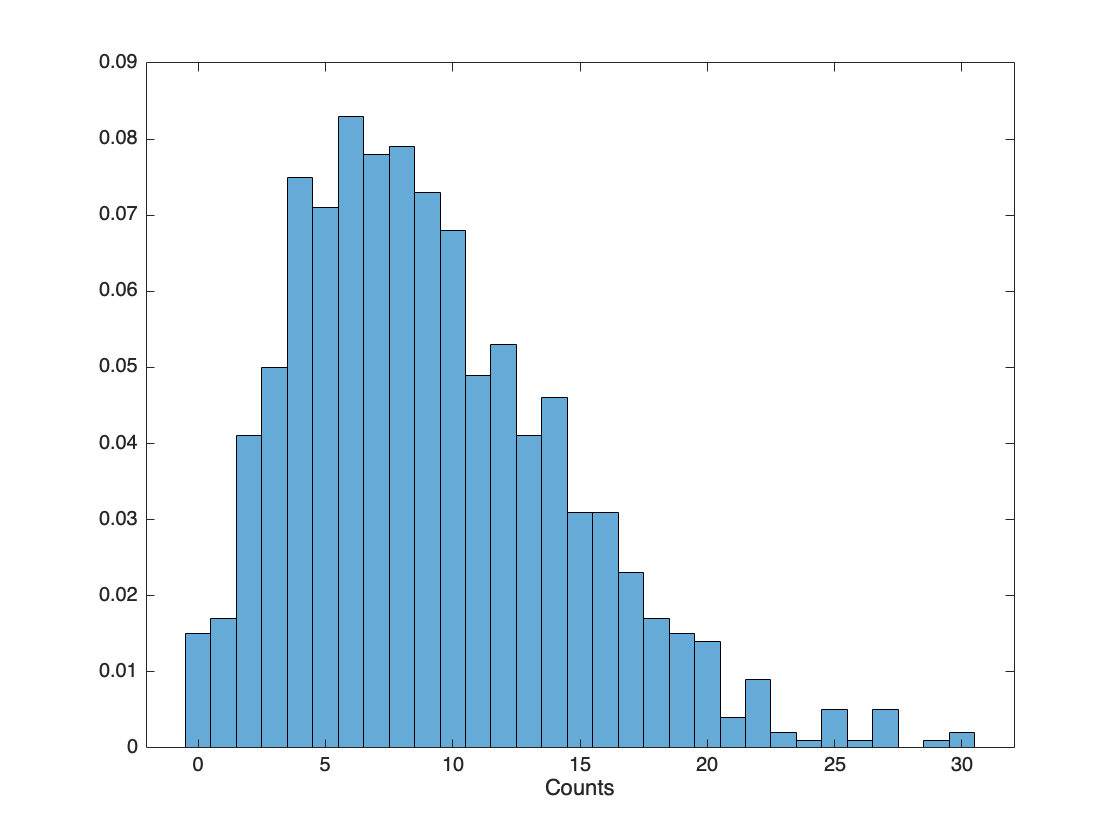

nSim = 1000;
count_A = NaN(nSim, 1);

for i = 1:nSim
    counts = rna_seq_sim(ti, poissrnd(ni), np);
    count_A(i) = counts(1); %tallies number of counts for the first gene
end 

figure('Name', "Question 8")
histogram(count_A, "Normalization", "pdf")
xlabel("Counts")

## Q9:

figure("Name","Question 9 and 10")
hold on
histogram(count_A, "Normalization", "pdf")
xlabel("Counts")
mc = mean(count_A); 
points = 0:1:25;
plot(points, poisspdf(points, mc))

## Q10:

params = nbinfit(count_A); 
plot(points, nbinpdf(points, params(1), params(2)))
legend("Observed Data", "Poisson Fit", "Negative Binomial Fit")